# **Exercise 38.6**

**1. Initialization**

Let A be the 100 x 100 tridiagonal symmetric matrix with 1, 2, ..., 100 on the diagonal and 1 on the sub- and superdiagonals, and set b = (1, 1, ..., 1)^T. 

total_step = 100; % The number of steps

%% Construct A %%
A = zeros(100, 100);
for i = 1:100
    A(i, i) = i;
    if (i+1 <= 100)
        A(i + 1, i) = 1; % subdiagonal
        A(i, i + 1) = 1; % superdiagonal
    end
end
K = cond(A); % condition number of A
%% Construct b %%
b = ones(100, 1);
A, b % Check

A =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     4     1     0     0     0     0     0     0     0     0     0     0   

b =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


res_norm_cg = zeros(1, total_step); 
actual_res_norm_cg = zeros(1, total_step);
res_norm_sd = zeros(1, total_step);
estimate_bound = zeros(1, total_step);

**2. Conjugate Gradient (CG) Iteration & Steepest Descent**

Take 100 steps of the CG and also the steepest descent iteration to approximately solve Ax = b.

xn_cg = 0; rn_cg = b ; pn_cg = rn_cg; % initial values for CG
xn_sd = 0; rn_sd = b ; pn_sd = rn_sd; % initial values for SD
for n = 1:total_step
    %% CG 
    an_cg = (rn_cg'*rn_cg)/(pn_cg' * (A * pn_cg)); % step length
    xn_cg = xn_cg + an_cg * pn_cg; % approximate solution
    prev_r = rn_cg; % r_(n-1)
    rn_cg = rn_cg - an_cg * (A * pn_cg); % residual 
    bn_cg = (rn_cg' * rn_cg) / (prev_r' * prev_r); % improvement this step
    pn_cg = rn_cg + bn_cg * pn_cg; % search direction

    %% SD
    an_sd = (rn_sd'*rn_sd)/(rn_sd' * (A * rn_sd)); % step length
    xn_sd = xn_sd + an_sd * pn_sd; % approximate solution
    rn_sd = rn_sd - an_sd * (A * pn_sd); % residual
    pn_sd = rn_sd; % search direction

    %% Save the data
    res_norm_cg(n) = norm(rn_cg); 
    actual_res_norm_cg(n) = norm(b - A * xn_cg);
    res_norm_sd(n) = norm(rn_sd);
    estimate_bound(n) = 2 * ((sqrt(K)-1)/(sqrt(K)+1))^n;
end

**3. Plot the result**

Produce a plot with four curves on it: the computed residual norms ||r_n||

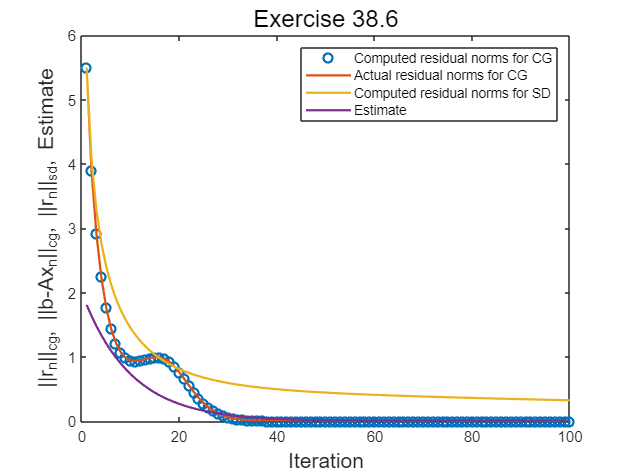

x = [1:total_step];
plot(x, res_norm_cg, 'o', x, actual_res_norm_cg, x, res_norm_sd, x, estimate_bound, 'LineWidth', 1.5); % To distinct actual residual and computed residual, plotting with dots
xlabel('Iteration', 'FontSize', 14);
ylabel('||r_n||_{cg}, ||b-Ax_n||_{cg}, ||r_n||_{sd}, Estimate', 'FontSize', 14);
legend('Computed residual norms for CG', 'Actual residual norms for CG', 'Computed residual norms for SD', 'Estimate')
title('Exercise 38.6', 'FontSize', 16);

**Comment**

First, there was no significant difference between the computed residual and the actual residual on the overall scale of the graph. (So for computed residual, I drew the dot graph instead of curve.)

And, we can see that SD is converging far slower than CG as the author said in Exercise 38.5 in the resulting plot. In case of CG, the residual norm started increasing at ~10 step, but it descreased well again. While CG can be seen that it converges well after ~20 steps, SD does not converge well even after 100 times. 